# CUDA Time Comparison Analysis

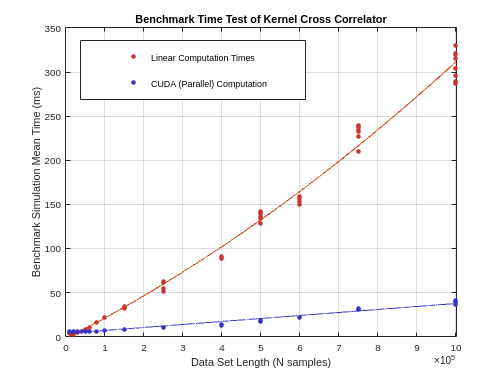

% --Setup
    clear; clc; format compact; close all; warning off;

% --Store Values (10,000 length)

    % --Regular 10,000 values
        reg_10_mean = [3.902, 3.964, 3.973, 3.984, 4.144];      % time in ms

    % --CUDA 10,000 values
        CUDA_10_mean = [5.726, 5.766, 5.735, 5.722, 5.684];     % time in ms

        length_10 = 10000.*ones(1, length(CUDA_10_mean));

% --Store Values (20,000 length)

    % --Regular 20,000 values
        reg_20_mean = [3.061, 2.905, 2.917, 2.962, 2.932];      % Time in ms
    
    % --CUDA 20,000 values
        CUDA_20_mean = [5.171, 5.202, 5.376, 5.356, 5.439];     % Time in ms
        length_20 = 20000.*ones(1, length(CUDA_20_mean));      
    

% --Store Values (30,000 length)

    % --Regular 30,000 values
        reg_30_mean = [4.883, 4.995, 4.923, 4.703, 4.721];

    % --CUDA 30,000 values
        CUDA_30_mean = [5.597, 5.594, 5.458, 5.603, 5.624];
        length_30 = 30000.*ones(1, length(CUDA_30_mean));
    

% --Store Values (length = 40,000)
       
    % --Regular 40,000 values
        reg_40_mean = [6.247, 6.146, 6.100, 6.120, 6.115];

    % --CUDA 40,000 values
        CUDA_40_mean = [5.755, 5.388, 5.660, 5.622, 5.607];
        length_40 = 40000.*ones(1,length(CUDA_40_mean));

% --Store Values (length = 50,000)
    
    % --Regular 50,000
        reg_50_mean = [8.165, 7.957, 8.242, 8.296, 8.309];

    % --CUDA 50,000 values
        CUDA_50_mean = [5.638, 5.641, 5.608, 5.828, 5.647];
        length_50 = 50000.*ones(1,length(CUDA_50_mean));    

% --Store Values (length = 60,000)
    
    % --Regular 60,000 values
        reg_60_mean = [10.199, 10.550, 10.415, 10.272, 10.158];

    % --CUDA 60,000 values
        CUDA_60_mean = [5.978, 5.689, 5.931, 5.776, 5.769];
        length_60 = 60000.*ones(1, length(CUDA_60_mean));
    
% --Store Values (length = 80,000)
    
    % --Regular 80,000 values
        reg_80_mean = [16.172, 15.982, 16.432, 16.011, 16.069];

    % --CUDA 80,000 values
        CUDA_80_mean = [6.210, 6.199, 5.957, 6.257, 6.278];
        length_80 = 80000.*ones(1, length(CUDA_80_mean));

% --Store Values (length = 100,000)
    
    % --Regular 100,000 values
        reg_100_mean = [21.358, 21.871, 21.686, 21.218, 22.091];

    % --CUDA 100,000 values
        CUDA_100_mean = [6.438, 6.442, 6.392, 6.456, 6.373];
        length_100 = 100000.*ones(1,length(CUDA_100_mean));

% --Store Values (length = 150,000)

    % --Regular 150,000 values
        reg_150_mean = [33.416, 32.400, 33.638];

    % --CUDA 100,000 values
        CUDA_150_mean = [7.863, 8.045, 7.897];
        length_150 = 150000.*ones(1, length(CUDA_150_mean));

% --Store Values (length = 250,000)

    % --Regular 250,000 values
        reg_250_mean = [62.131, 61.940, 61.237, 54.166, 51.609];

    % --CUDA 250,000 values
        CUDA_250_mean = [10.110, 10.084, 10.068, 9.963, 10.072];
        length_250 = 250000.*ones(1, length(CUDA_250_mean));

% --Store Values (length = 400,000)
    
    % --Regular 400,000 values
        reg_400_mean = [88.195, 90.993, 89.623];

    % --CUDA 400,000 values
        CUDA_400_mean = [13.141, 13.264, 13.250];
        length_400 = 400000 .* ones(1, length(CUDA_400_mean));

% --Store Values (length = 500,000)
    
    % --Regular 500,000 values
        reg_500_mean = [141.420, 136.316, 139.912, 133.844, 128.166];

    % --CUDA 500,000 values
        CUDA_500_mean = [17.473, 17.759, 17.838, 18.421, 18.705];
        length_500 = 500000.*ones(1, length(CUDA_500_mean));

% --Store Values (length = 600,000)
    
    % --Reg values 
        reg_600_mean = [158.767, 156.91, 150.273, 153.287];

    % --CUDA Values
        CUDA_600_mean = [21.799, 21.910, 21.179, 21.150];
        length_600 = 600000.*ones(1, length(CUDA_600_mean));

% --Store values (length = 750,000)

    % --Regular 750,000 values
        reg_750_mean = [226.740, 239.580, 237.507, 233.318, 232.625, 210.261];

    % --CUDA 750,000 values
        CUDA_750_mean = [30.305, 30.340, 32.239, 31.359, 31.106, 30.594]; 
        length_750 = 750000.*ones(1, length(CUDA_750_mean));

% --Creating line sets for data regression
    
    % --Regular 1,000,000 values
        reg_1000_mean = [315.064, 330.123, 320.977, 320.155, 303.411, 289.610, 295.612, 287.071];

    % --CUDA 1,000,000 values
        CUDA_1000_mean = [39.645, 39.253, 40.433, 40.485, 36.611, 37.793, 37.199, 39.079];
        length_1000 = 1000000.*ones(1, length(CUDA_1000_mean));

% --Compile all data together 
    reg_means = [reg_10_mean, reg_20_mean, reg_30_mean, reg_40_mean, reg_50_mean, reg_60_mean, reg_80_mean, reg_100_mean, reg_150_mean ...
                 reg_250_mean, reg_400_mean, reg_500_mean, reg_600_mean, reg_750_mean, reg_1000_mean];
    CUDA_means = [CUDA_10_mean, CUDA_20_mean, CUDA_30_mean, CUDA_40_mean, CUDA_50_mean, CUDA_60_mean, CUDA_80_mean, CUDA_100_mean...
                  CUDA_150_mean, CUDA_250_mean, CUDA_400_mean, CUDA_500_mean, CUDA_600_mean, CUDA_750_mean, CUDA_1000_mean];
    lengths = [length_10, length_20, length_30, length_40, length_50, length_60, length_80, length_100, length_150, length_250 ...
               length_400, length_500, length_600, length_750, length_1000];

% --Plot
    figure()
    plot(lengths, reg_means,'.', 'Color', [0.8 0.2 0.2], 'MarkerSize',14)
        hold on
        xlim([0 1001000])
        ylim([0 350])
        grid on
        xlabel('Data Set Length (N samples)')
        ylabel('Benchmark Simulation Mean Time (ms)')
        title('Benchmark Time Test of Kernel Cross Correlator')
    plot(lengths, CUDA_means, '.', 'Color', [0.2 0.2 0.8], 'MarkerSize',14)
    legend('Linear Computation Times', 'CUDA (Parallel) Computation', 'Autoupdate','off')

% --Fit the regression
    p = polyfit(lengths, reg_means, 2);
    x1 = 0:100:1000000;
    f1 = polyval(p,x1);
    plot(x1,f1, 'Color', [0.8 0.2 0.])

% --CUDA fit regression
    p = polyfit(lengths, CUDA_means, 1);
    x1 = 0:100:1000000;
    f1 = polyval(p,x1);
    plot(x1,f1, 'Color', [0.2 0.2 0.8])
    % legend('Linear Computation Times', 'CUDA (Parallel) Computation', 'Regular Quadratic Regression Model', 'Parallel Linear Regression Model')
    legend("Position", [0.16072,0.73706,0.44464,0.15595])

% --Fitlm
    fitlm(lengths, CUDA_means, "linear")

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE        tStat       pValue  
                   __________    _________    ______    __________
    (Intercept)        3.5381      0.26677    13.263     5.175e-21
    x1             3.3987e-05    5.915e-07    57.458    6.7537e-62

Number of observations: 74, Error degrees of freedom: 72
Root Mean Squared Error: 1.71
R-squared: 0.979,  Adjusted R-Squared: 0.978
F-statistic vs. constant model: 3.3e+03, p-value = 6.75e-62

    fitlm(lengths, reg_means, "quadratic")

ans = Linear regression model:
    y ~ 1 + x1 + x1^2

Estimated Coefficients:
                    Estimate         SE         tStat       pValue  
                   __________    __________    _______    __________
    (Intercept)       -2.3218        1.5616    -1.4868        0.1415
    x1             0.00022503    1.1065e-05     20.336    2.4988e-31
    x1^2           8.8783e-11    1.1482e-11     7.7322    5.2434e-11

Number of observations: 74, Error degrees of freedom: 71
Root Mean Squared Error: 8.28
R-squared: 0.994,  Adjusted R-Squared: 0.994
F-statistic vs. constant model: 5.8e+03, p-value = 2.13e-79